clear
clf
I_range = [.1 5 10 15 20 25 30 35 40]; %sweep of window area

%colors = ['#FF0000'; '#0000FF'; '#FF0000'; '#0000FF'; '#0000FF'];

JouleperDollar = ones([1, length(I_range)]);

for x = 1:length(I_range)
    I = I_range(x);
    [T_hour,M, cost] = HouseEnergy(I);
    hold on
    last2days = find(T_hour>(max(T_hour)-48))
    plot((T_hour(last2days)-max(T_hour)+48), M(last2days,1));% ,'Color', colors(x,:));
    minloc = find(M(:,1)==min(M(:,1)));% find location of the minimum temperature point and mark it on the plot
    %plot(T_hour(minloc), M(minloc,1),'*', 'Color', colors(x,:));
    mlen45 = (length(M)*4/5)
    JouleperDollar(x) = trapz(T_hour(last2days), (M(last2days,1))) / cost;
    temppercent(x) = (min(M(last2days,1))-288.706) / (cost);
end

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

last2days =        91979
       91980
       91981
       91982
       91983
       91984
       91985
       91986
       91987
       91988


mlen45 = 7.7262e+04

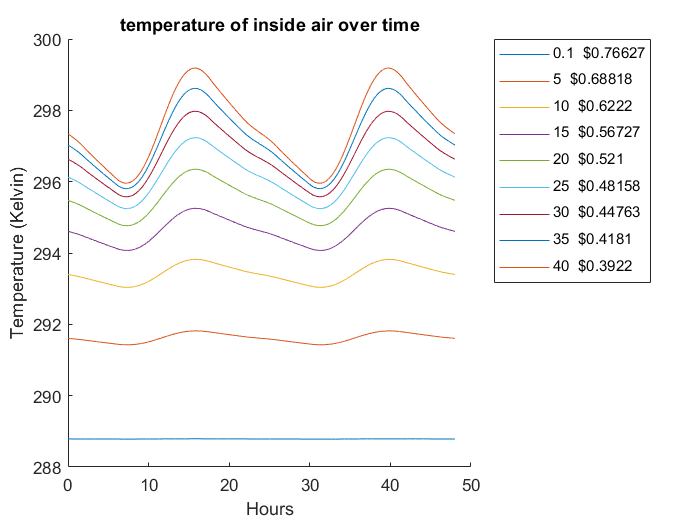


legend(string(I_range)+ " _ $" + string(JouleperDollar), "Location","bestoutside");
xlabel("Hours");
ylabel("Temperature (Kelvin)");
title("temperature of inside air over time")

Analysis: Currently, the model is exhibiting unnatural behavior by immediately shooting all stocks towards the energy of the sun. In all seriousness, it seems that my ode is adding energy on to itself instead of updating the stocks. I tried to diagnose and resolve the error myself, but was not able to. Office hours were also canceled so I will go to the next available. Once I have the code done, I will be able to determine the energy per dollar depending on the ratio of area of window to wall. I also do not have a new and improved model as I spent most of my time creating the mathematical equations and since I still do not have a working model, I have not been able to improve it. Even though an extension was requested, we did try to prepare the code to the best of our abilities. 